# DSZOB, cvičenie 4.

## **Zadanie:**

## **Úloha 1 **

Vygenerujte si náhodne nasledujúce signály podľa predchádzajúcich cvičení:

- jednoduchý signál

- zložený signál

- jednoduchý signál so zníženou vzorkovacou frekvenciou s porušením Nyquistovho teorému

Z daných signálov vyberte vhodnú vzorku 512 hodnôt, vypočítajte a vizualizujte Diskrétnu Fourierovu transformáciu:

- Podľa definície

- S využitím funkcie fft()

- Násobením vstupného vektora s Fourierovou transformačnou maticou (viď. Prednáška)

## Pomôcka (definícia):

- počet prvkov vo vektore

- index spektrálnych koeficientov

- index vzorku vo vstupnom vektore (číslicový signál o dĺžke N)

**Postup vhodne dokumentuje (Code/Text bloky)!**

## **Riešenie:**

fs = 10000;
sx = 0:1/fs:3;
fs_lt_nyq = 8000;
sx_lt_nyq = (0:1/fs_lt_nyq:3);
sy1 = sin(2*pi*sx*1000);
sy2 = sin(2*pi*sx*2000) + sin(2*pi*sx*3000) + sin(2*pi*sx*4000);
sy3 = sin(2*pi*sx_lt_nyq*5000);
y1 = sy1(1:512);
y2 = sy2(1:512);
y3 = sy3(1:512);

## Jednoduchý signál:

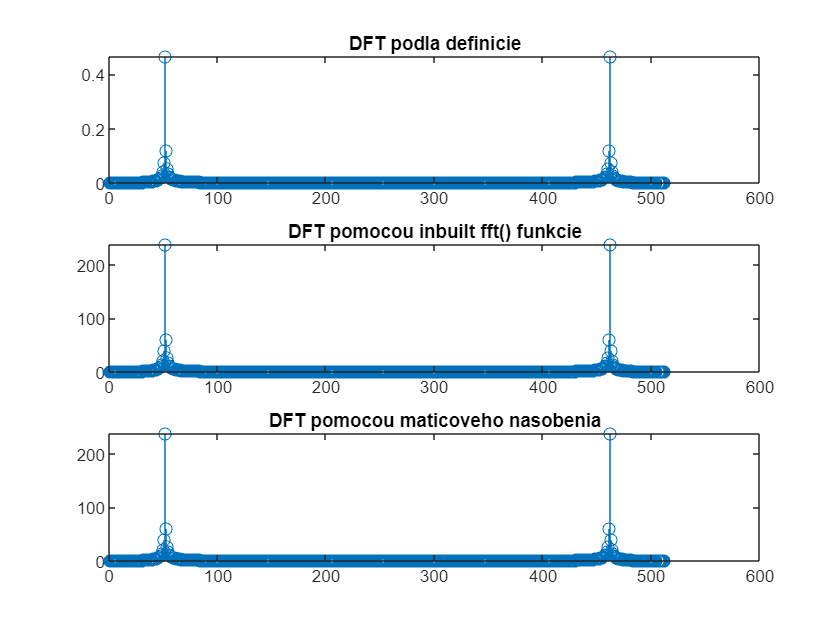

figure();
subplot(3,1,1);
dft1_def = custom_dft(y1);
stem(abs(dft1_def))
title('DFT podla definicie')
subplot(3,1,2);
dft1_fft = fft(y1);
stem(abs(dft1_fft))
title('DFT pomocou inbuilt fft() funkcie')
subplot(3,1,3);
dft1_mtx = y1 * dftmtx(512);
stem(abs(dft1_mtx))
title('DFT pomocou maticoveho nasobenia')

## Zložený signál:

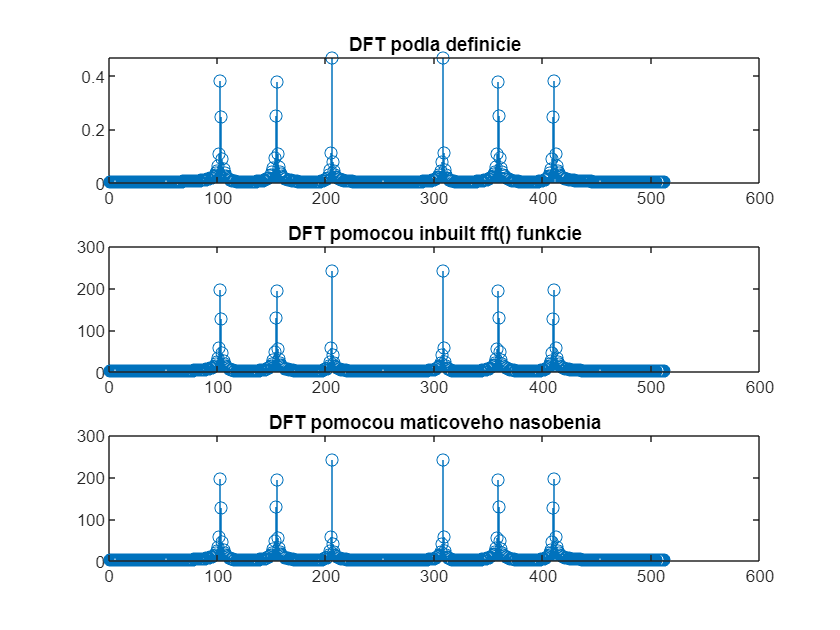

figure();
subplot(3,1,1);
dft2_def = custom_dft(y2);
stem(abs(dft2_def))
title('DFT podla definicie')
subplot(3,1,2);
dft2_fft = fft(y2);
stem(abs(dft2_fft))
title('DFT pomocou inbuilt fft() funkcie')
subplot(3,1,3);
dft2_mtx = y2 * dftmtx(512);
stem(abs(dft2_mtx))
title('DFT pomocou maticoveho nasobenia')

## Jednoduchý signál porušujúci nyquistov teorém:

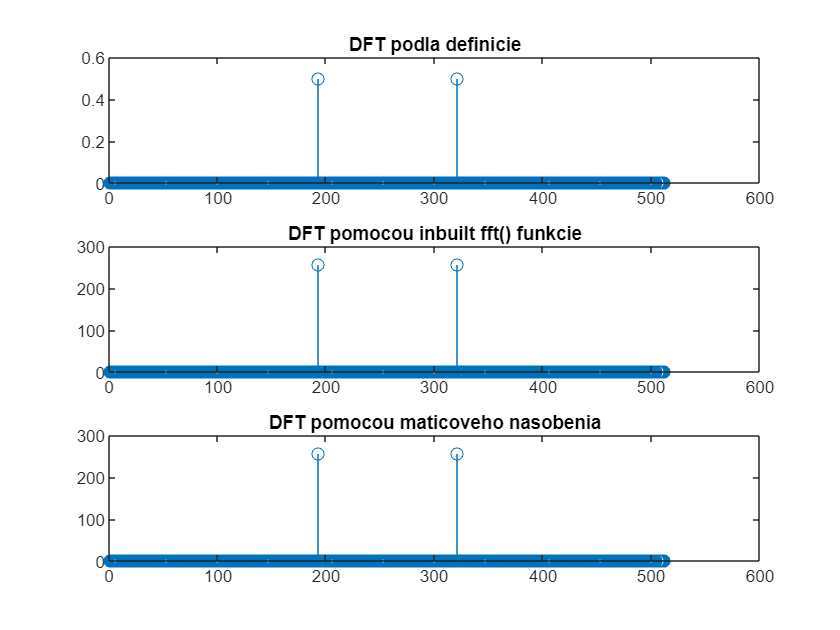

figure();
subplot(3,1,1);
dft3_def = custom_dft(y3);
stem(abs(dft3_def))
title('DFT podla definicie')
subplot(3,1,2);
dft3_fft = fft(y3);
stem(abs(dft3_fft))
title('DFT pomocou inbuilt fft() funkcie')
subplot(3,1,3);
dft3_mtx = y3 * dftmtx(512);
stem(abs(dft3_mtx))
title('DFT pomocou maticoveho nasobenia')

Aj moja custom funkcia aj vstavané funkcie na výpočet DFT generujú rovnaké frekvenčné spektrum (Pre všetky 3 signály), len os Y je inak naškálovaná. To však neovplyvňuje výpovednú hodnotu získaného spektra.

## **Úloha 2**

Vygenerujte signál pre časový úsek 0-1s: 

- Zložený signál obsahujúci 5 rôznych frekvencií a so vzorkovacou frekvenciou 44.1kHz. (vznikne aditívne so zvolenými násobnými koeficientami)

Vypočítajte Fourierovo spektrum (funkcia **fft**) zo selektovaného kratšieho časového úseku tohto signálu nasledujúcimi spôsobmi:

- Hammingovo okienko (windowing)

- Pravouhlé okienko (windowing)

- Vyberte vhodný počet vzoriek signálu a pred výpočtom spektra ho doplňte nulami na dĺžku rovnú najbližšej vyššej mocnine čísla 2 (“zero padding”)

Pomôcka: Pre vizualizáciu použite funkciu **stem.** funkcia **fftshift** Vám posunie spektrá

**Otázky:**

- Akú výhodu nám prináša “zero padding” pri výpočte spektra signálu?

- Aký bol rozdiel vo výslednej Fourierovej transformácii pri použití Hammingovho a Pravouhlého okienka?

fs = 44100;
sx = 0:1/fs:1;
sy = sin(2*pi*sx*2000) + sin(2*pi*sx*4000) + sin(2*pi*sx*6000) + sin(2*pi*sx*8000) + sin(2*pi*sx*10000);
x = sx(1:512);
y = sy(1:512);

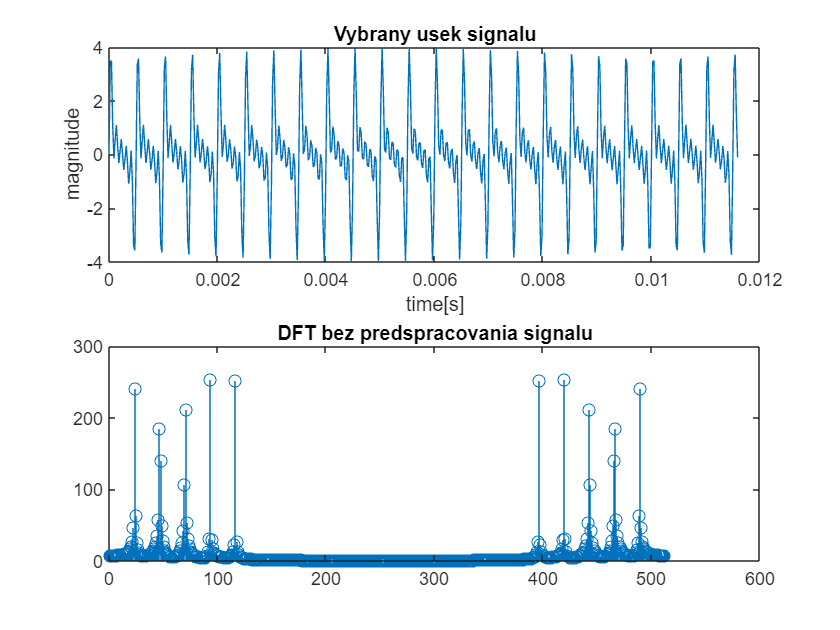

figure();
subplot(2,1,1);
plot(x,y)
title('Vybrany usek signalu')
xlabel('time[s]')
ylabel('magnitude')
subplot(2,1,2);
dft_plain = fft(y);
stem(abs(dft_plain))
title('DFT bez predspracovania signalu')

Bez predspracovania signálu vidíme, že DFT vykazuje okrem frekvencii, z ktorých je signál zložený aj viaceré frekvencie, ktoré v tomto signále vôbec nie sú prítomné.

## Hamming window:

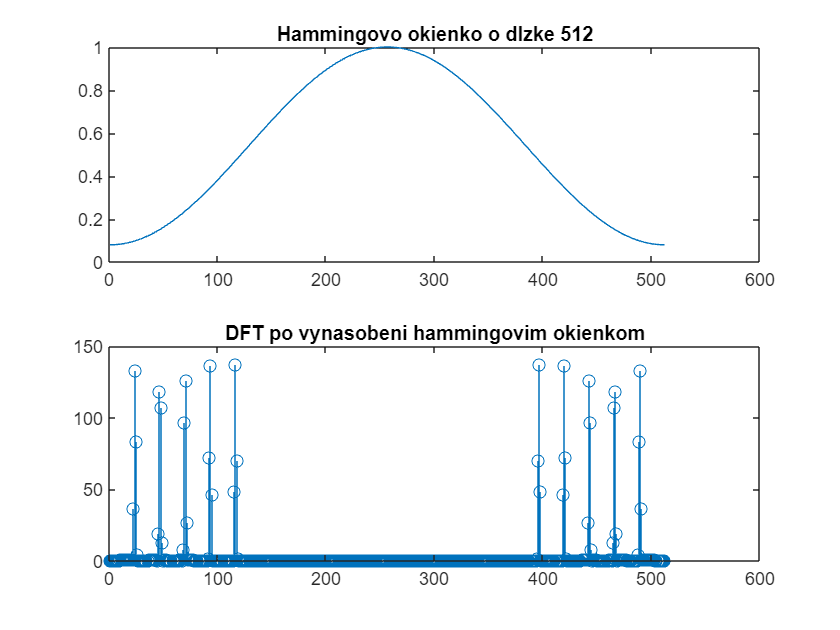

figure();
subplot(2,1,1);
ham = hamming(512)';
plot(ham)
title('Hammingovo okienko o dlzke 512')
subplot(2,1,2);
dft_hamming = fft(y .* ham);
stem(abs(dft_hamming))
title('DFT po vynasobeni hammingovim okienkom')

Použitím hammingovho okienka na predspracovanie signálu dosiahneme čistejší výsledok z DFT, kde súmenej dominantné neexistujúce frekvencie.

## Pravouhlé okienko:

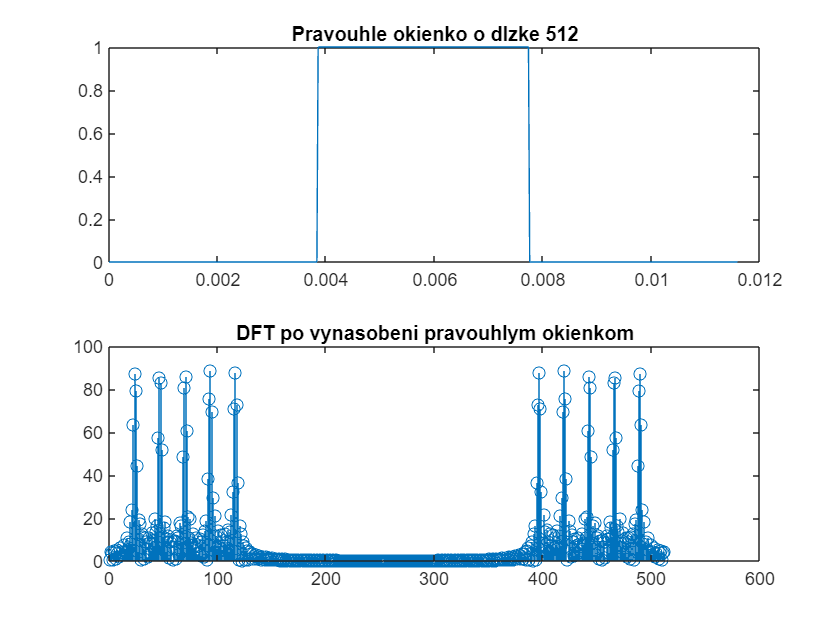

figure();
subplot(2,1,1);
rect = zeros(1,512);
rect(171:342) = 1;
plot(x, rect)
title('Pravouhle okienko o dlzke 512')
subplot(2,1,2);
dft_rectangle = fft(y .* rect);
stem(abs(dft_rectangle))
title('DFT po vynasobeni pravouhlym okienkom')

Použitím pravouhlého okienka výsledná DFT produkuje spektrum, ktoré je ešte vzdialenejšie od reality ako bez predspracovania.

## Zero padding:

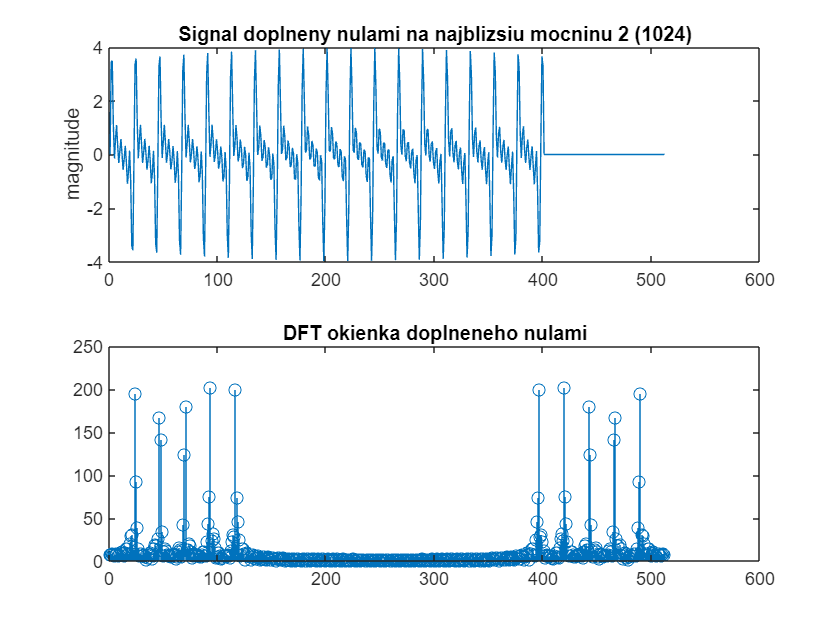

figure();
subplot(2,1,1);
padded = zeros(1,512);
padded(1:400) = y(1:400);
plot(padded);
title('Signal doplneny nulami na najblizsiu mocninu 2 (1024)')
ylabel('magnitude')
subplot(2,1,2);
dft_padded = fft(padded);
stem(abs(dft_padded))
title('DFT okienka doplneneho nulami')

Aplikovaním zero paddingu na predspracovanie signálu, ktorý bol skrátený na nie mocninu 2, dostávame podobný výsledok ako bez spracovania, ale dominantné frekvencie sú mierne zvýraznené. Tu je vidieť, že ak nemáme vzorku signálu, ktorá nie je v žiadúcej dĺžke pridaním núl vyriešime tento problém a získame tak dobrý výsledok ako keby sme mali vzorku správnej  dĺžky.

## Porovnanie výsledkov:

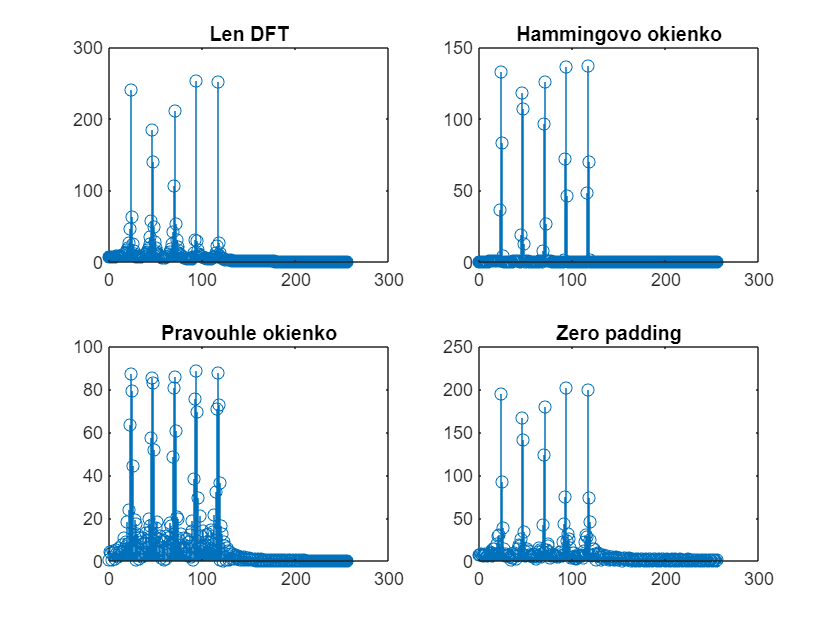

figure();
subplot(2,2,1);
tmp = abs(dft_plain); 
stem(tmp(1:256))
title('Len DFT')
subplot(2,2,2);
tmp = abs(dft_hamming);
stem(tmp(1:256))
title('Hammingovo okienko')
subplot(2,2,3);
tmp = abs(dft_rectangle);
stem(tmp(1:256))
title('Pravouhle okienko')
subplot(2,2,4);
tmp = abs(dft_padded);
stem(tmp(1:256))
title('Zero padding')

Z tohto porovnania môžeme vidieť, že na dosiahnutie načistejšieho frekvenčného spektra, pomocou DFT, je najvhodnejšie použiť hammingovo okienko.

function f = custom_dft(y)
    M = length(y);
    f = zeros(1, M);
    e = exp(1);    
    
    for u = 0:M-1
        t = 0;
        for x = 0:M-1
            t = t + y(x+1)*e^((-j)*2*pi*x*u / M);
        end
        t = t/M;
        f(u + 1) = t;
    end
end